# Preprocessing 2: Channel Information and Down-Sampling

In this livescript, we will prepare our EEG dataset by removing any non-EEG channels and down sample the data. For further analysis, we need to get rid of any external channels or any other non-EEG data as these may affect our results. Moreover, downsampling our data will save us storage space and speed up any analysis we perform. 

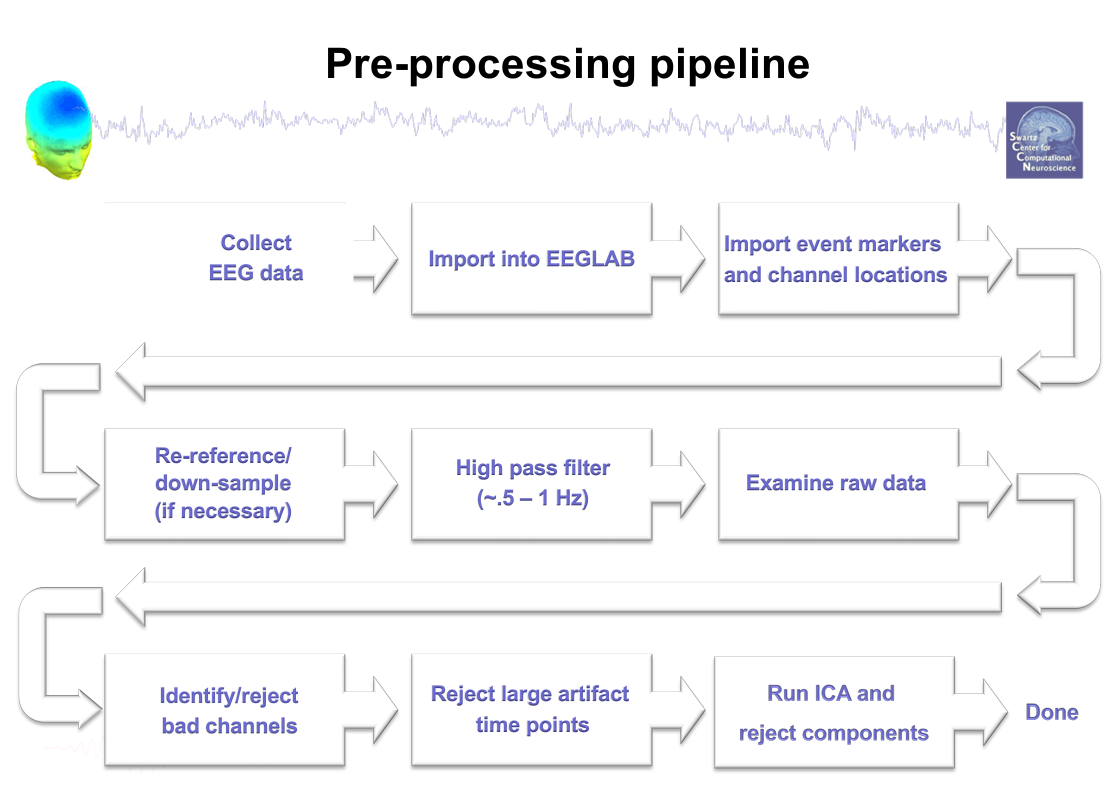

## Channel Information

There are many different EEG headsets. The number of channels may differ among these headset widely (16, 32, 64, 128, 160, or 256 channels). Moreover, they may have different layouts and non-standard labels. Standard channel names include Fpz, O1, or O2. Headsets made by Biosemi use non-standard labels (ABC labels). Here is a sample layout with Biosemi labels in blue and standard labels in violet: 

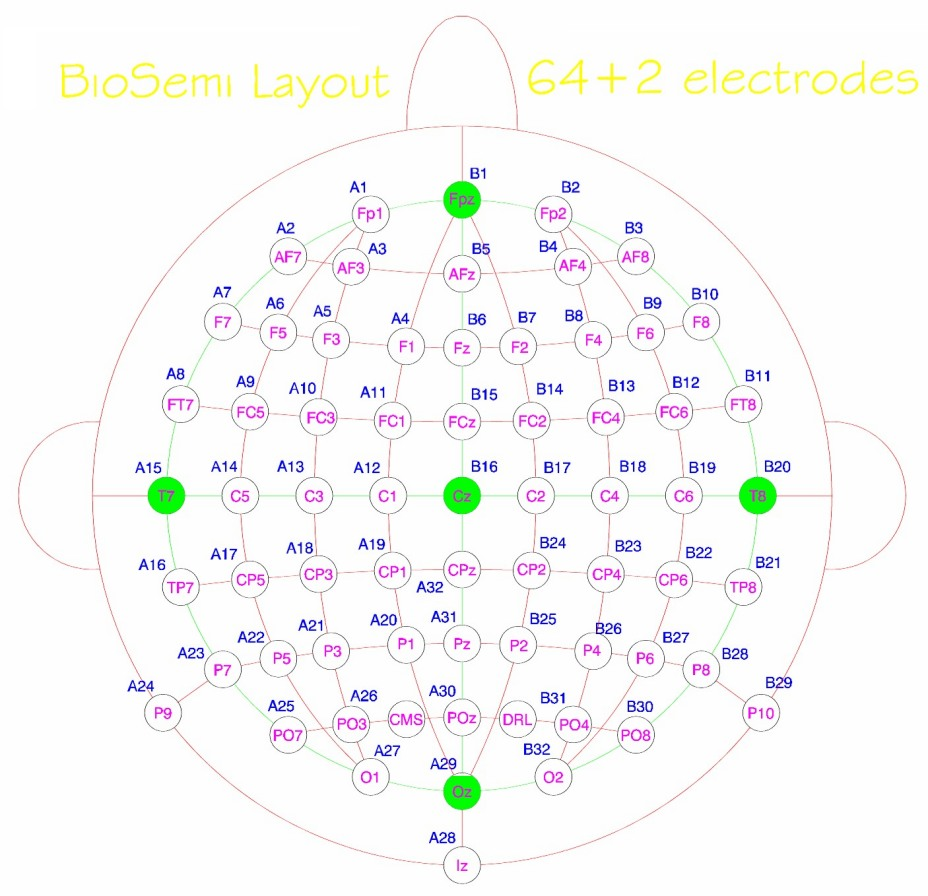

Additionally, some headsets may have external channels which can be used to measure additional physiological signals (e.g. ECG). Gyroscope and accelerometer data may also accompany the dataset. These non-EEG channels need to be removed to do any further processing or analysis. 

Unfornately, sometimes the datasets do not have any channel metadata (e.g. coordinates, channel names, etc.). That's why EEGLAB has an option to load in channel information from a external file. These files are provided by either other researchers or the headset manufacturers. For the dataset we are looking at, we do not have channel metadata in the dataset, but we do have an external file load in the channel information. We can also change the non-standard labels to standard ones by using EEGLAB. First thing is first, let us define the path to our datasets and initialize EEGLAB, which may be familiar with the code block from the previous tutorial: 

% Change this to the path where eeglab folder is
%eeglab_path = fullfile(matlabroot,'toolbox','eeglab');
%addpath(genpath(eeglab_path));

%Initializing EEGlab
eeglab;
%Directory where are data are located: 
dir_data = 'data'; %Change this to where your data is

%Directory where our LSL recordings are located: 
dir_xdf = fullfile(dir_data,'xdf');

%Directory where headset data are located: 
dir_head = fullfile(dir_data,'headset_channel_locations');

%Directory where we will save our data: 
dir_set = fullfile(dir_data,'set');

%Using an if/else statement to check if folder already exists: 
if not(isfolder(dir_set))
    fprintf('Creating a new folder at %s',dir_set);
    mkdir(dir_set); % if the folder doesn't exist, we will create it
    disp('Done!')
else
    fprintf('%s already exists!',dir_set)
end

We will define what channels we want to remove as a cell array with these non-EEG channel labels. Unfortunately, I got these non-EEG channels labels by manually looking at the dataset, so we can't really automate this part without looking into the dataset. Here are the channels we want to remove

%Channels We Want to Remove which include external channels and trigger:
rmCh_labels = {...
    'Trig1','EX1','EX2','EX3','EX4','EX5','EX6','EX7','EX8'...
    };

Let us load in an LSL recording with **pop_loadxdf**: 

%Format specifier for our recording: 
file_spec = 'vrcct_%s_%s_%s.%s'; %Four char formatting operators

%Let us define the name parts of our file: 
sub = 'p16'; %subject or participant 16
study = 'prestudy'; %First session of experiment
part = 'condition'; %meditation part of session
ext = 'xdf'; %File extension of our dataset (LSL recording)

%Let us use sprintf to define a dataset name: 
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Loading LSL recording: 
EEG = pop_loadxdf( ...
    fullfile(dir_xdf,file_name));

Next, we'll use the [**pop_select**](https://github.com/NBT-Analytics/EEGLABSVN/blob/master/functions/popfunc/pop_select.m) function to remove non-EEG channels. To remove non-EEG channels, we need two inputs: the EEG struct and the 'nochannel' input (a cell array of channel labels you want to remove). To load in channel information, we use [**pop_chanedit**](https://github.com/sccn/eeglab/blob/develop/functions/popfunc/pop_chanedit.m) and requires two inputs: EEG struct and the 'load' input (the path to the channel information). Then we can recenter channel locations with **pop_chanedit** using the 'eval' input. 

% Removing non-EEG channels:
EEG = pop_select(EEG, 'nochannel', rmCh_labels);

%Loading in Channel information:
EEG = pop_chanedit( ...
    EEG, ...
    'load',fullfile(dir_head,'bio_semi_64.ced'));

%Re-centering channel locations: 
EEG = pop_chanedit( ...
    EEG, ...
    'eval','chans = pop_chancenter( chans, [],[]);');

We can plot the channel locations to see all channels using topoplot. To plot channel locations, we can use the following piece of code: 

%Plotting channel locations
figure;
topoplot( ...
    [],EEG.chanlocs, ...
    'style','blank', ...
    'electrodes','labelpoint', ...
    'chaninfo',EEG.chaninfo);

## Downsampling

Downsampling is very straight-forward. The reason we do it is to save storage space and to decrease computational time in further analysis (e.g. independent component analysis). To do this, we use the the **pop_resample **that requires two inputs: the EEG struct and the sampling rate you want to resample to. In this case, we use 250 Hz. Let's see how to do this

%Saving original Sampling rate:
srate_org = EEG.srate;

%Downsampling data to 250 Hz:
EEG = pop_resample(EEG, 250);

%New sampling rate: 
srate_new = EEG.srate;

%Showing results:
fprintf( ...
    'The original sampling rate is %i Hz and was resampled to %i Hz.', ...
    srate_org, srate_new);

## Saving Dataset

Finally, let's save our data, so we can use it in future tutorials. 

% We change the extension for our file name to 'set'
ext = 'set';
part = 'condition_raw';
file_name = sprintf( ...
    file_spec, ...
    sub,study,part,ext);

%Saving our dataset: 
EEG = pop_saveset( ...
    EEG, ...
    'filename',file_name, ...
    'filepath',dir_set, ... %notice that we save in dir_set
    'savemode','twofiles');

## Conclusion

In this tutorial, we learned how to import channel information using an external file. We verified it by plotting it with topoplot. Downsampling is very straight-forward, and we perform it to save storage space and decrease computational time in other preprocessing functions and analysis. 